# Solution to the *Land Cover Classification *exercise

## 1. Load Data

Load the data in `satdata.mat`.

load satdata

The matrix `satData` consists of information from a *Landsat* satellite image, including multispectral values of pixels, associated with various types of land. The objective is to predict the type of land cover (class) in `satClass`, given these multispectral values. There are six land cover classes, collected in the `landclass` variable.

The data is available from the Machine Learning Repository at the University of California, Irvine:[https://archive.ics.uci.edu/ml/datasets/Statlog+(Landsat+Satellite)](https://archive.ics.uci.edu/ml/datasets/Statlog+(Landsat+Satellite))

## 2. Partition data

Partition the data so that 70% is used for training and 30% for validation. 

pt = cvpartition(satClass,'holdout',0.3); 
predTrain = satData(training(pt),:);
classTrain = satClass(training(pt));
predValid = satData(test(pt),:);
classValid = satClass(test(pt));

## 3. Fit k-nn classifier

Create a *k*-Nearest Neighbor classification model with the training data, with *k* = 5.

knnClassifier = fitcknn(predTrain,classTrain,'Numneighbors',5);

## 4. Evaluate quality of classifier

Determine the validation error.

loss(knnClassifier,predValid,classValid)

ans = 0.1037

## 5. Create Confusion Matrix and visualize

Evaluate the classification by constructing a confusion matrix and visualize the groupings.

yPred = predict(knnClassifier,predValid);

c =    243    12    71    27    48    61
     8    47    47    16    15    69
    55    48   154    30    42    78
    36    30    32    30    15    45
    55    16    35    21    51    44
    63    58    68    63    41   156


lbls = 6×1 categorical array
     1 
     2 
     3 
     4 
     5 
     6 


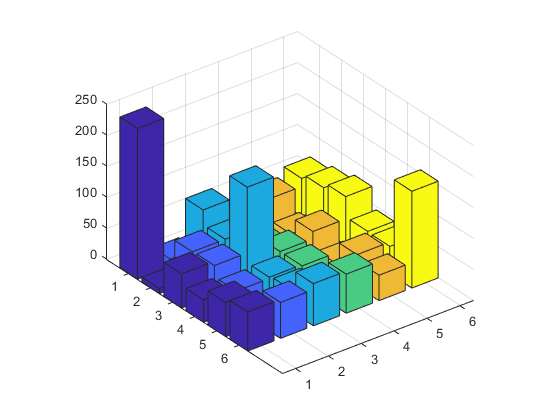

[c,lbls] = confusionmat(yPred,classValid)

bar3(c)
ax = gca;
ax.XTickLabel = categories(lbls);
ax.YTickLabel = categories(lbls);

## Bonus. Fit data with a classification tree

Fit the training data again, using a classification tree for the model, and repeat steps 4 and 5.

t = fitctree(predTrain,classTrain);

Visualize tree

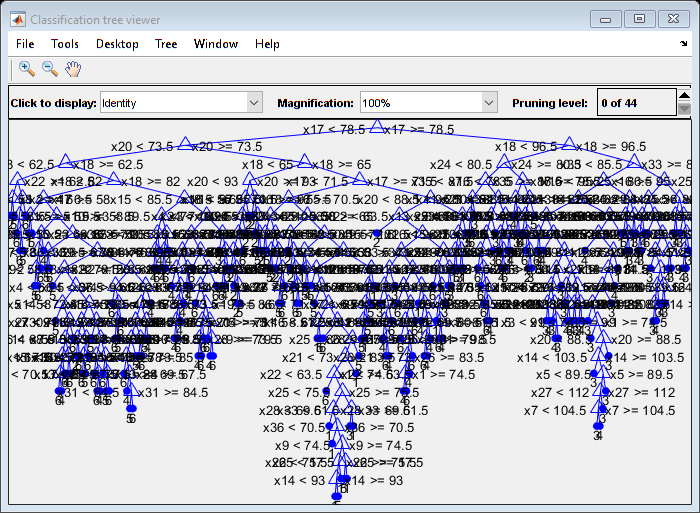

view(t,'Mode','graph')

Evaluate quality

loss(t,predValid,classValid)

ans = 0.1561